# SPIFI OTF/PSFs for SDI try

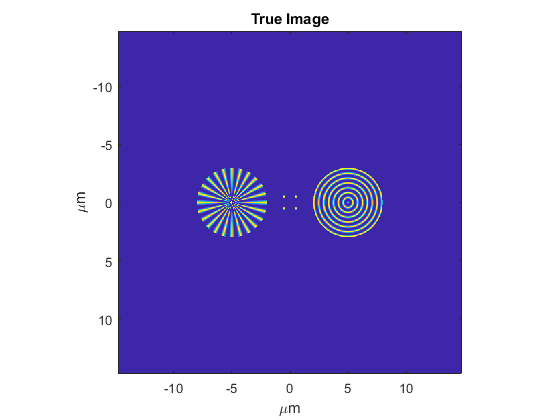

addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SPIFIandCHIRPTSims")

%load grids

x=load('xspatvec.mat');
x=x.Expression1;
fx=load('xspatfreq.mat');
fx=fx.Expression1;
y=load('yspatvec.mat');
y=y.Expression1;
fy=load('yspatfreq.mat');
fy=fy.Expression1;
trueimage=load("trueimage.mat");
trueimage=trueimage.Expression1;
figure; imagesc(x,y,trueimage)
xlabel('\mum')
ylabel('\mum')
axis square
title('True Image')

Load Blurry Images

% Noisy ones
for jj=1:4
    s=load(strcat('imgN2',num2str(jj),'.mat'));
    imgN2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('imgN3',num2str(jj),'.mat'));
    imgN3(:,:,jj)=s.Expression1;
end    
% Normalized Versions
for jj=1:4
    
    imgN2N(:,:,jj)=Norm(imgN2(:,:,jj));
end
for jj=1:6
    
    imgN3N(:,:,jj)=Norm(imgN3(:,:,jj));
end 

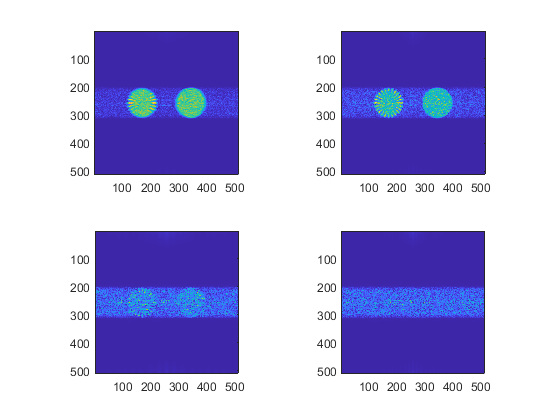


figure;
subplot(2,2,1)
imagesc(imgN2(:,:,1))
axis square
subplot(2,2,2)
imagesc(imgN2(:,:,2))
axis square
subplot(2,2,3)
imagesc(imgN2(:,:,3))
axis square
subplot(2,2,4)
imagesc(imgN2(:,:,4))
axis square

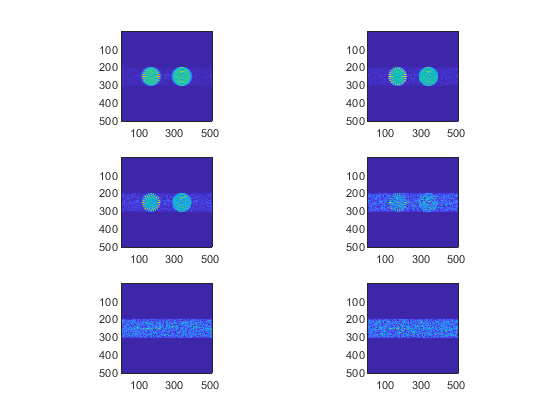


figure;
subplot(3,2,1)
imagesc(imgN3(:,:,1))
axis square
subplot(3,2,2)
imagesc(imgN3(:,:,2))
axis square
subplot(3,2,3)
imagesc(imgN3(:,:,3))
axis square
subplot(3,2,4)
imagesc(imgN3(:,:,4))
axis square
subplot(3,2,5)
imagesc(imgN3(:,:,5))
axis square
subplot(3,2,6)
imagesc(imgN3(:,:,6))
axis square

Load Noise Free Versions

% Noise Free ones
for jj=1:4
    s=load(strcat('imgNF2',num2str(jj),'.mat'));
    imgNF2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('imgNF3',num2str(jj),'.mat'));
    imgNF3(:,:,jj)=s.Expression1;
end    
% Normalized Versions
for jj=1:4
    
    imgNF2N(:,:,jj)=Norm(imgNF2(:,:,jj));
end
for jj=1:6
    
    imgNF3N(:,:,jj)=Norm(imgNF3(:,:,jj));
end   

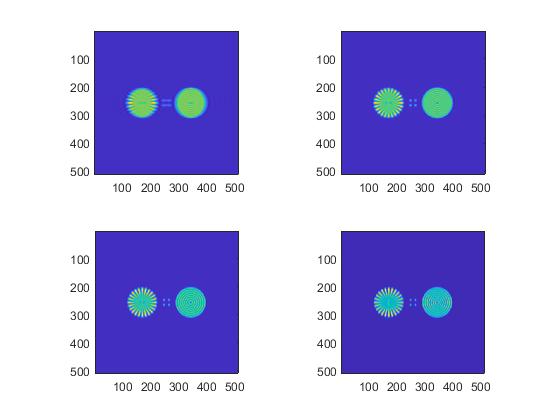

figure;
subplot(2,2,1)
imagesc(imgNF2(:,:,1))
axis square
subplot(2,2,2)
imagesc(imgNF2(:,:,2))
axis square
subplot(2,2,3)
imagesc(imgNF2(:,:,3))
axis square
subplot(2,2,4)
imagesc(imgNF2(:,:,4))
axis square

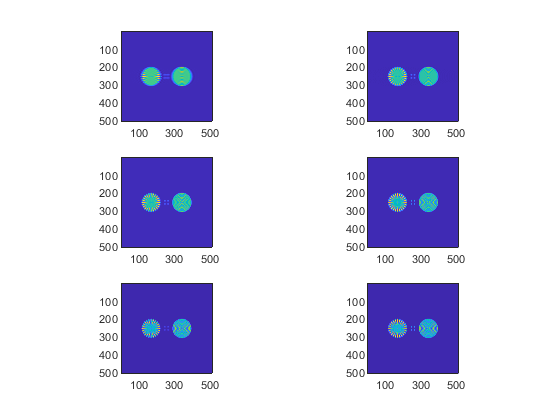


figure;
subplot(3,2,1)
imagesc(imgNF3(:,:,1))
axis square
subplot(3,2,2)
imagesc(imgNF3(:,:,2))
axis square
subplot(3,2,3)
imagesc(imgNF3(:,:,3))
axis square
subplot(3,2,4)
imagesc(imgNF3(:,:,4))
axis square
subplot(3,2,5)
imagesc(imgNF3(:,:,5))
axis square
subplot(3,2,6)
imagesc(imgNF3(:,:,6))
axis square

Load OTFs

for jj=1:4
    s=load(strcat('OTF2',num2str(jj),'.mat'));
    OTF2(:,:,jj)=s.Expression1;
end
for jj=1:6
    s=load(strcat('OTF3',num2str(jj),'.mat'));
    OTF3(:,:,jj)=s.Expression1;
end    

Turn into PSFs (Above OTFs are not complex??)

for ii=1:4
    PSF2(:,:,ii)=abs(ifftshift(ifft2(OTF2(:,:,ii))));
end
for ii=1:6
    PSF3(:,:,ii)=abs(ifftshift(ifft2(OTF3(:,:,ii))));
end
% Normalized Versions
for ii=1:4
    PSF2N(:,:,ii)=Norm(PSF2(:,:,ii));
end
for ii=1:6
    PSF3N(:,:,ii)=Norm(PSF3(:,:,ii));
end

s=size(PSF2);
param2=reshape(PSF2N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgNF2,[s(1) s(1)*s(3)]);
bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=8000;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 7606.380258 seconds.


recMPIMNF2=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 1.1680e-06

%figure; imagesc(reshape(X2,size(CAM)))

save('imgNF2Recon.mat','recMPIMNF2','-v7.3','-nocompression');

load('imgNF2Recon.mat');

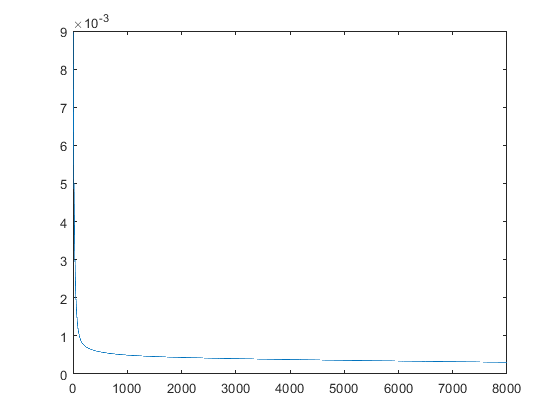

for ii=1:size(recMPIMNF2,3)
    errorimNF2(ii)=immse(trueimage,recMPIMNF2(:,:,ii));
end
figure; plot(errorimNF2)

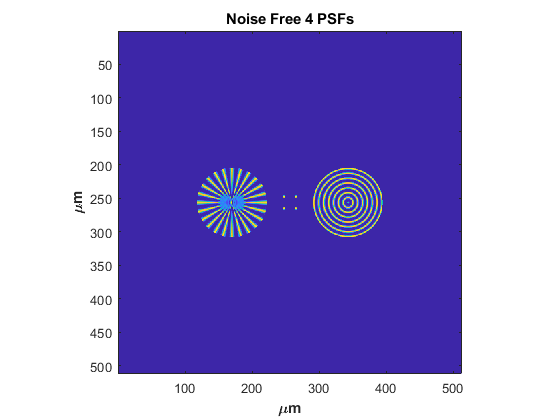

figure; imagesc(recMPIMNF2(:,:,end))
axis square
xlabel('\mum','FontWeight',"bold")
ylabel('\mum','FontWeight',"bold")
title('Noise Free 4 PSFs')

k=1:500;
%options  = IRmrnsd('defaults');
[Xmrnsd infomrnsd]=IRmrnsd(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',100, 'x_true','none', ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off'));

Reached maximum number of iterations



recMPIMNF2mrnsd=reshape(Xmrnsd,[s(1) s(1) length(k)]);

s=size(PSF3N);
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgNF3,[s(1) s(1)*s(3)]);
bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=4000;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 5284.744285 seconds.


recMPIMNF3=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 2.0365e-06

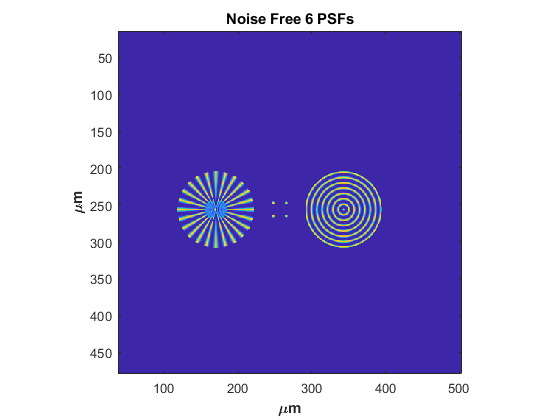

figure; imagesc(recMPIMNF3(:,:,end))
axis square
xlabel('\mum','FontWeight',"bold")
ylabel('\mum','FontWeight',"bold")
title('Noise Free 6 PSFs')

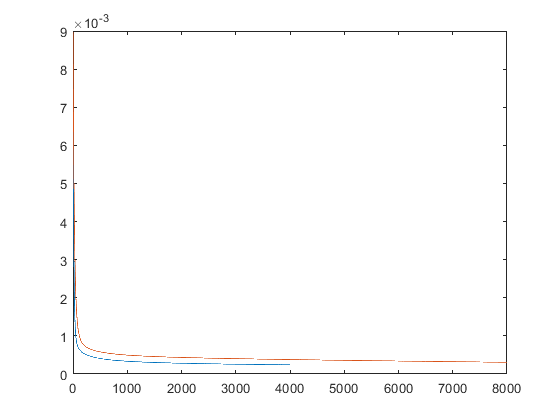

for ii=1:size(recMPIMNF3,3)
    errorimNF3(ii)=immse(trueimage,recMPIMNF3(:,:,ii));
end
figure; plot(errorimNF3)
hold on
plot(errorimNF2)

save('imgNF3Recon.mat','recMPIMNF3','-v7.3','-nocompression');

s=size(PSF3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgN3,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=400;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 487.279789 seconds.


recMPIMN3=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0019

save('imgN3Recon.mat','recMPIMN3','-v7.3','-nocompression');

k=1:500;
%options  = IRmrnsd('defaults');
[Xmrnsd infomrnsd]=IRmrnsd(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',100, 'x_true','none', ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off'));

Reached maximum number of iterations



recMPIMN3mrnsd=reshape(Xmrnsd,[s(1) s(1) length(k)]);

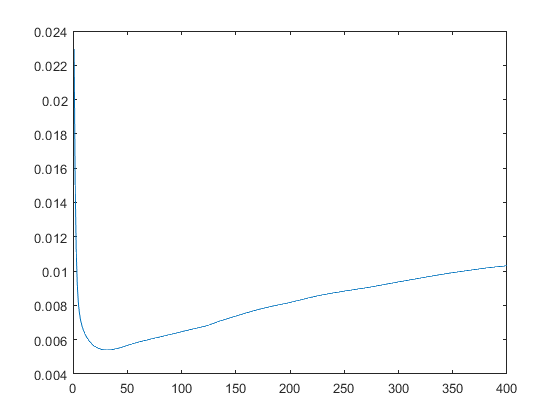

for ii=1:size(recMPIMN3,3)
    errorimN3(ii)=immse(Norm(trueimage),Norm(recMPIMN3(:,:,ii)));
end
figure; plot(errorimN3)

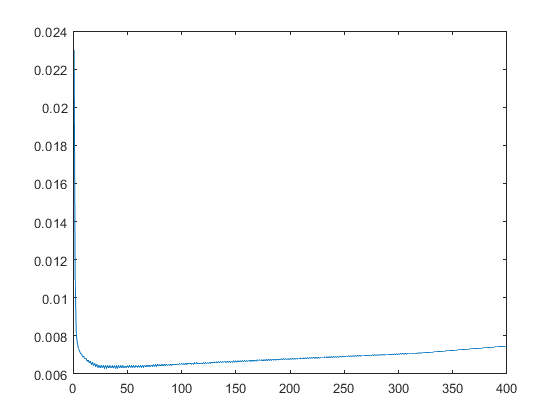

for ii=1:size(recMPIMN3,3)
    errorimN3mrnsd(ii)=immse(Norm(trueimage),Norm(recMPIMN3mrnsd(:,:,ii)));
end
figure; plot(errorimN3mrnsd)

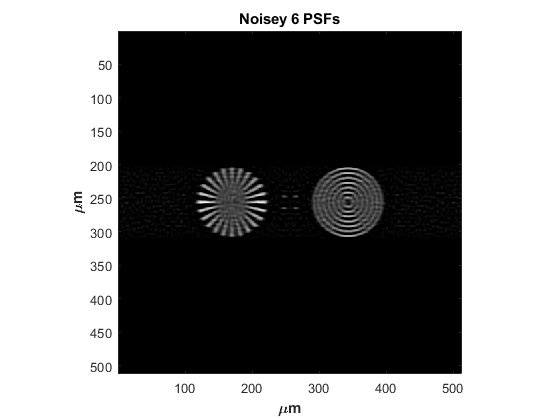

figure; imagesc(recMPIMN3(:,:,28))
axis square
xlabel('\mum','FontWeight',"bold")
ylabel('\mum','FontWeight',"bold")
title('Noisey 6 PSFs')
colormap gray

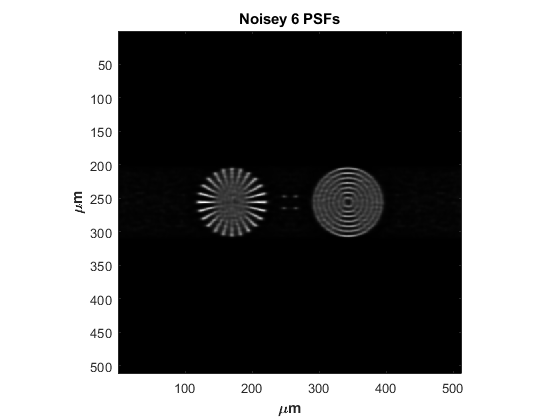

figure; imagesc(recMPIMN3mrnsd(:,:,28))
axis square
xlabel('\mum','FontWeight',"bold")
ylabel('\mum','FontWeight',"bold")
title('Noisey 6 PSFs')
colormap gray

s=size(PSF2N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSF2N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgN2,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=400;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.1, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 319.235920 seconds.


recMPIMN2=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0017

save('imgN2Recon.mat','recMPIMN2','-v7.3','-nocompression');

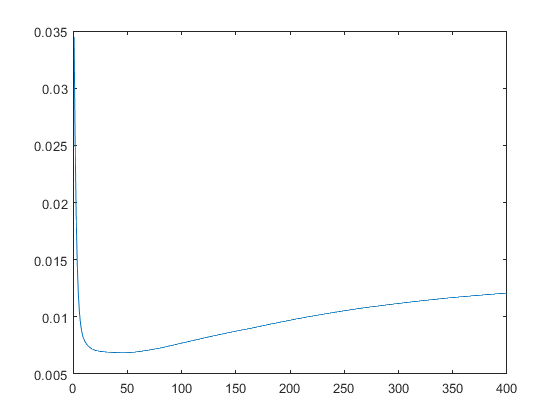

for ii=1:size(recMPIMN2,3)
    errorimrecMPIMN2(ii)=immse(Norm(trueimage),Norm(recMPIMN2(:,:,ii)));
end
figure; plot(errorimrecMPIMN2)

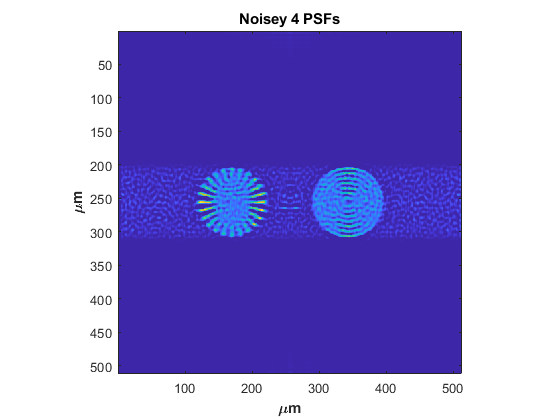

figure; imagesc(recMPIMN2(:,:,46))
axis square
xlabel('\mum','FontWeight',"bold")
ylabel('\mum','FontWeight',"bold")
title('Noisey 4 PSFs')

s=size(PSF3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgN3,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) AcnvsetOp(vin,param2,transp_flag,512,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=400;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Index in position 2 is invalid. Array indices must be positive integers or logical values.

Error in AcnvsetOp (line 15)
        vout=vout(obsize-obsize/2:obsize+(obsize/2-1),(size(vout)+1)/2-(obsize/2):(size(vout)+1)/2+(obsize/2-1));

Error in SDIMPSPIFITry (line 283)
Ac2=@(vin,transp_flag) AcnvsetOp(vin,param2,transp_flag,512,size(bdn));%,size(obbb),size(o

%end
toc;
recMPIMN3v2=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

s=size(PSF3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgN3N,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=400;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 524.761393 seconds.


recMPIMN3Norm=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0093

## Add own version of Noise

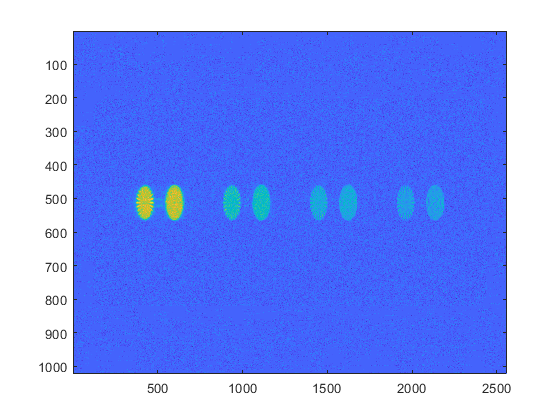

GaussAmp=.05;
PhotCnt=20;
s=size(PSF2);
param2=reshape(PSF2N,[s(1) s(1)*s(3)]);%OBBB2;
%Imdata=reshape(imgNF2,[s(1) s(1)*s(3)]);
ImdataGN2=conv_fft2(param2,Norm(trueimage));
s=size(PSF3);
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
%Imdata=reshape(imgNF2,[s(1) s(1)*s(3)]);
ImdataGN3=conv_fft2(param2,Norm(trueimage));
%Cnvset=Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im)));
ImDataNoiseGN2=addNoise(ImdataGN2(:),GaussAmp,PhotCnt);
ImDataNoiseGN2=reshape(ImDataNoiseGN2,size(ImdataGN2));
ImDataNoiseGN2(isnan(ImDataNoiseGN2))=0;

ImDataNoiseGN3=addNoise(ImdataGN3(:),GaussAmp,PhotCnt);
ImDataNoiseGN3=reshape(ImDataNoiseGN3,size(ImdataGN3));
ImDataNoiseGN3(isnan(ImDataNoiseGN3))=0;
figure; imagesc(ImDataNoiseGN2)

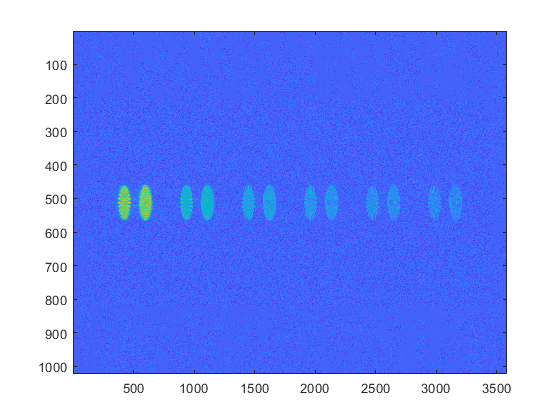

figure; imagesc(ImDataNoiseGN3)

s=size(PSF3N);
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
% Imdata=reshape(imgNF3,[s(1) s(1)*s(3)]);
% bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(ImDataNoiseGN3));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=400;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,ImDataNoiseGN3(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 504.014881 seconds.


recMPIMGN3=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0289

save('recGN3.mat','recMPIMGN3');

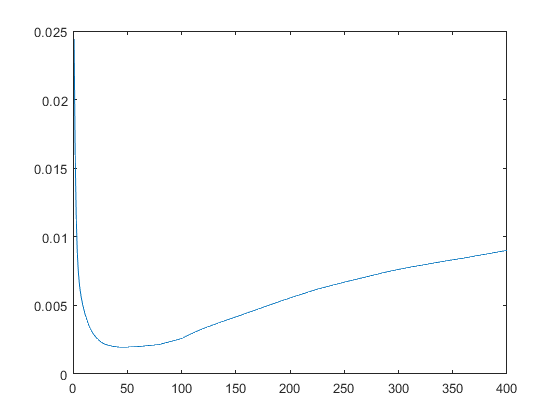

for ii=1:size(recMPIMGN3,3)
    errorrecMPIMGN3(ii)=immse(Norm(trueimage),Norm(recMPIMGN3(:,:,ii)));
end
figure; plot(errorrecMPIMGN3)

s=size(PSF2N);
param2=reshape(PSF2N,[s(1) s(1)*s(3)]);%OBBB2;
% Imdata=reshape(imgNF3,[s(1) s(1)*s(3)]);
% bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(ImDataNoiseGN2));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=400;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,ImDataNoiseGN2(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 320.754162 seconds.


recMPIMGN2=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0222

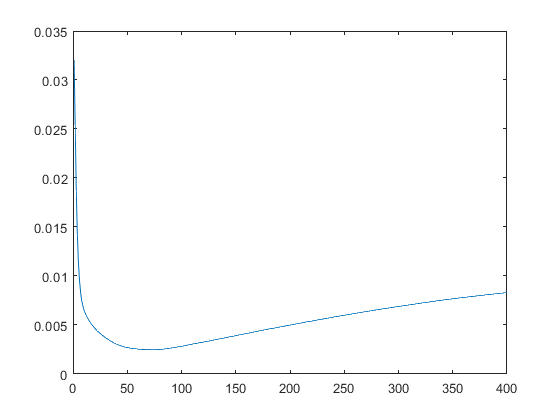

for ii=1:size(recMPIMGN3,3)
    errorrecMPIMGN2(ii)=immse(Norm(trueimage),Norm(recMPIMGN2(:,:,ii)));
end
figure; plot(errorrecMPIMGN2)

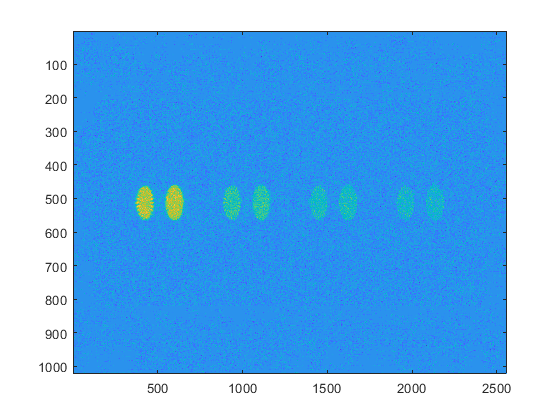

GaussAmp=.1;
PhotCnt=20;
s=size(PSF2);
param2=reshape(PSF2N,[s(1) s(1)*s(3)]);%OBBB2;
%Imdata=reshape(imgNF2,[s(1) s(1)*s(3)]);
ImdataGN2=conv_fft2(param2,Norm(trueimage));
s=size(PSF3);
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
%Imdata=reshape(imgNF2,[s(1) s(1)*s(3)]);
ImdataGN3=conv_fft2(param2,Norm(trueimage));
%Cnvset=Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im)));
ImDataNoiseGN2v2=addNoise(ImdataGN2(:),GaussAmp,PhotCnt);
ImDataNoiseGN2v2=reshape(ImDataNoiseGN2v2,size(ImdataGN2));
ImDataNoiseGN2v2(isnan(ImDataNoiseGN2v2))=0;

ImDataNoiseGN3v2=addNoise(ImdataGN3(:),GaussAmp,PhotCnt);
ImDataNoiseGN3v2=reshape(ImDataNoiseGN3v2,size(ImdataGN3));
ImDataNoiseGN3v2(isnan(ImDataNoiseGN3v2))=0;
figure; imagesc(ImDataNoiseGN2v2)

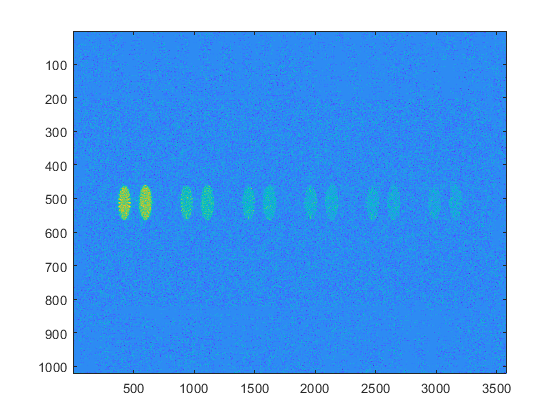

figure; imagesc(ImDataNoiseGN3v2)

s=size(PSF3N);
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
% Imdata=reshape(imgNF3,[s(1) s(1)*s(3)]);
% bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(ImDataNoiseGN3));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=400;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,ImDataNoiseGN3v2(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 558.765407 seconds.


recMPIMGN3v2=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0559


s=size(PSF2N);
param2=reshape(PSF2N,[s(1) s(1)*s(3)]);%OBBB2;
% Imdata=reshape(imgNF3,[s(1) s(1)*s(3)]);
% bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(ImDataNoiseGN2));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=400;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,ImDataNoiseGN2v2(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.001, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 337.847715 seconds.


recMPIMGN2v2=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0456

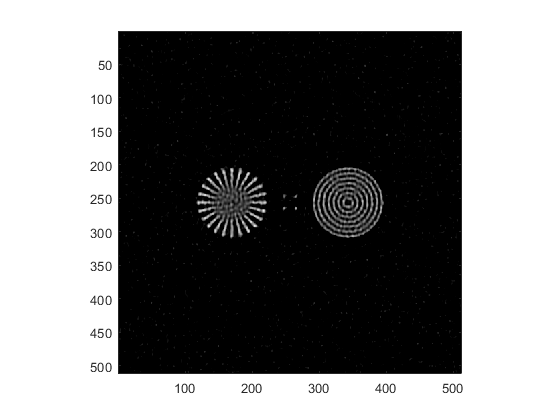

for ii=1:size(recMPIMGN3,3)
    errorrecMPIMGN2v2(ii)=immse(Norm(trueimage),Norm(recMPIMGN2v2(:,:,ii)));
end
for ii=1:size(recMPIMGN3,3)
    errorrecMPIMGN3v2(ii)=immse(Norm(trueimage),Norm(recMPIMGN3v2(:,:,ii)));
end
[eval2v2 locm2v2]=min(errorrecMPIMGN2v2);
[eval3v2 locm3v2]=min(errorrecMPIMGN3v2);
figure; imagesc(recMPIMGN2v2(:,:,locm2v2))
axis square
colormap gray

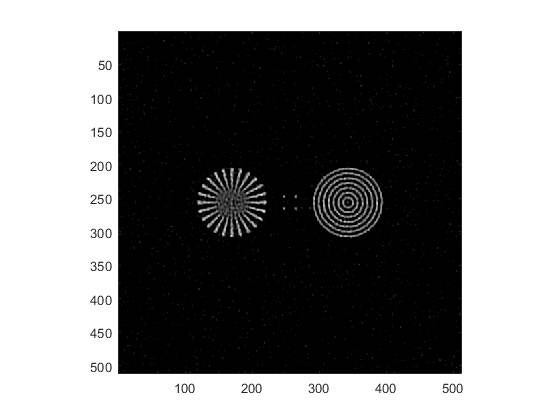

figure; imagesc(recMPIMGN3v2(:,:,locm3v2))
axis square
colormap gray

save('NoisyrecsMPimg23.mat','recMPIMGN2v2','recMPIMGN3v2')

imgN2GN=addNoise(imgNF2(:),GaussAmp*.1,PhotCnt);
imgN2GN=reshape(imgN2GN,size(imgNF2));
imgN2GN(isnan(imgN2GN))=0;

imgN3GN=addNoise(imgNF3(:),GaussAmp*.1,PhotCnt);
imgN3GN=reshape(imgN3GN,size(imgNF3));
imgN3GN(isnan(imgN3GN))=0;

imgN2GNv2=addNoise(imgN2(:),GaussAmp*.1,PhotCnt);
imgN2GNv2=reshape(imgN2GNv2,size(imgN2));
imgN2GNv2(isnan(imgN2GNv2))=0;

imgN3GNv2=addNoise(imgN3(:),GaussAmp*.1,PhotCnt);
imgN3GNv2=reshape(imgN3GNv2,size(imgN3));
imgN3GNv2(isnan(imgN3GNv2))=0;

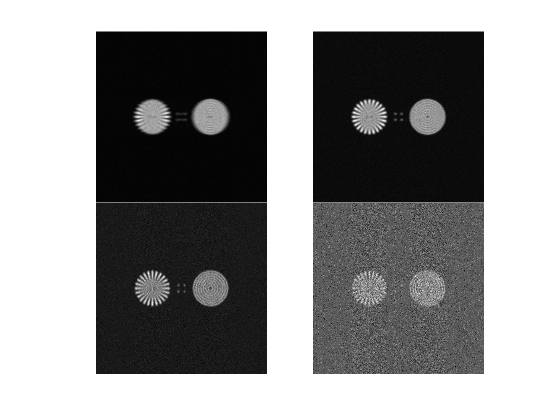

% figure; imagesc(imgN2GN(:,:,1))
figure;
t = tiledlayout(2,2);
t.TileSpacing = 'none';
% Tile 1
nexttile
imagesc(imgN2GN(:,:,1))
axis square
colormap gray
axis off
% Tile 2
nexttile
imagesc(imgN2GN(:,:,2))
axis square
colormap gray
axis off

% Tile 3
nexttile
imagesc(imgN2GN(:,:,3))
axis square
colormap gray
axis off

% Tile 4
nexttile
imagesc(imgN2GN(:,:,4))
axis square
colormap gray
axis off

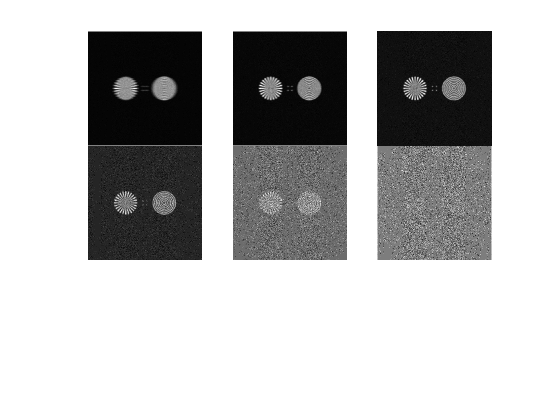




% figure; imagesc(imgN2GN(:,:,1))
figure;
t2 = tiledlayout(3,3);
t2.TileSpacing = 'none';
% Tile 1
nexttile
imagesc(imgN3GN(:,:,1))
axis square
colormap gray
axis off
% Tile 2
nexttile
imagesc(imgN3GN(:,:,2))
axis square
colormap gray
axis off

% Tile 3
nexttile
imagesc(imgN3GN(:,:,3))
axis square
colormap gray
axis off

% Tile 4
nexttile
imagesc(imgN3GN(:,:,4))
axis square
colormap gray
axis off

nexttile
imagesc(imgN3GN(:,:,5))
axis square
colormap gray
axis off

nexttile
imagesc(imgN3GN(:,:,6))
axis square
colormap gray
axis off

%t.Padding = 'none';

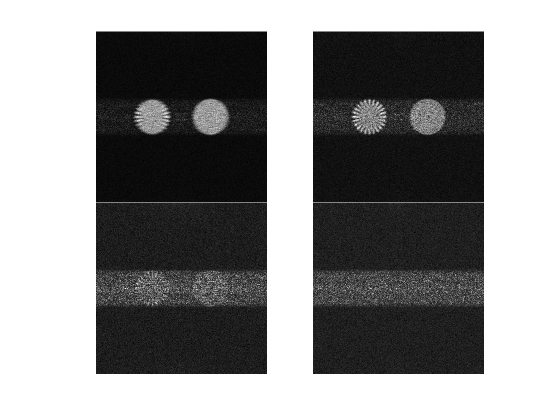

% figure; imagesc(imgN2GN(:,:,1))
figure;
t = tiledlayout(2,2);
t.TileSpacing = 'none';
% Tile 1
nexttile
imagesc(imgN2GNv2(:,:,1))
axis square
colormap gray
axis off
% Tile 2
nexttile
imagesc(imgN2GNv2(:,:,2))
axis square
colormap gray
axis off

% Tile 3
nexttile
imagesc(imgN2GNv2(:,:,3))
axis square
colormap gray
axis off

% Tile 4
nexttile
imagesc(imgN2GNv2(:,:,4))
axis square
colormap gray
axis off

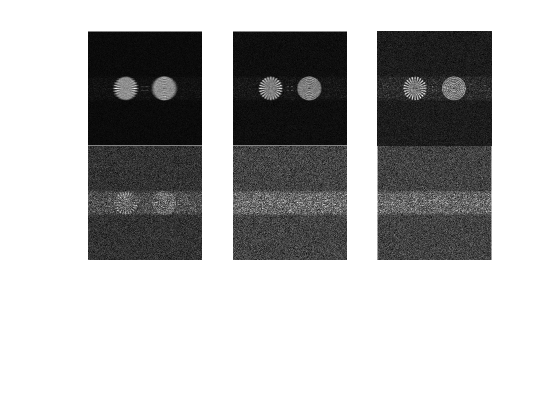




% figure; imagesc(imgN2GN(:,:,1))
figure;
t2 = tiledlayout(3,3);
t2.TileSpacing = 'none';
% Tile 1
nexttile
imagesc(imgN3GNv2(:,:,1))
axis square
colormap gray
axis off
% Tile 2
nexttile
imagesc(imgN3GNv2(:,:,2))
axis square
colormap gray
axis off

% Tile 3
nexttile
imagesc(imgN3GNv2(:,:,3))
axis square
colormap gray
axis off

% Tile 4
nexttile
imagesc(imgN3GNv2(:,:,4))
axis square
colormap gray
axis off

nexttile
imagesc(imgN3GNv2(:,:,5))
axis square
colormap gray
axis off

nexttile
imagesc(imgN3GNv2(:,:,6))
axis square
colormap gray
axis off

%t.Padding = 'none';

s=size(PSF2N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSF2N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgN2GN,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=400;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 324.227540 seconds.


recMPIMGN2v3=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0049


s=size(PSF3N);
delta=zeros(size(trueimage));
delta(end/2,end/2)=1;
param2=reshape(PSF3N,[s(1) s(1)*s(3)]);%OBBB2;
Imdata=reshape(imgN3GN,[s(1) s(1)*s(3)]);
bdn=circshift(circshift(conv_fft2(Imdata,delta),1,2),1,1);
%bdn=conv_fft2(param2,Norm(trueimage));
% bdn2=imnoise(Norm(conv_fft2(reshape(psft2camf,[s(1) s(1)*length(dcSAX)]),Norm(Im))),'gaussian',.01,.0001);
Ac2=@(vin,transp_flag) Cnv2Dns(vin,param2,transp_flag,s(1)^2,size(bdn));%,size(obbb),size(obbb));%,size(obbb),size(obbb));
%Ac1=@(vin,transp_flag) Cnv2D(vin,param1,transp_flag);%,length(psf2(:)),size(b3));
tic;
miter=400;%400;
k=1:miter;
%for i=1:5
[X4 info3]=IRfista(Ac2,bdn(:),k,struct('x0','none', 'MaxIter',miter, 'x_true',trueimage(:), ...
    'NoiseLevel','none', 'eta',1.01, 'NE_Rtol',1e-12, 'IterBar','on', ...
    'NoStop','off', 'RegParam',.01, 'xMin',0, 'xMax',inf, 'xEnergy','none'));

Reached maximum number of iterations


%end
toc;

Elapsed time is 512.547579 seconds.


recMPIMGN3v3=reshape(X4,[s(1) s(1) miter]);
min(info3.NE_Rnrm)

ans = 0.0068

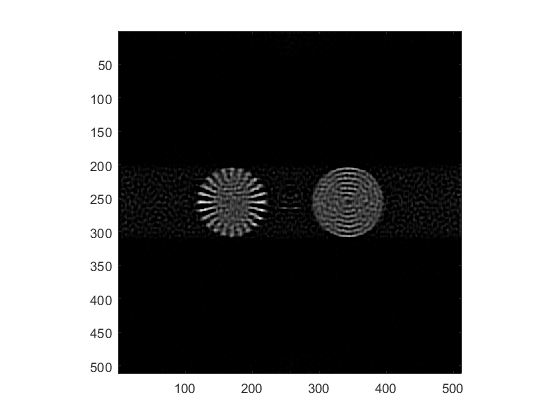

for ii=1:size(recMPIMGN3,3)
    errorrecMPIMGN2v3(ii)=immse(Norm(trueimage),Norm(recMPIMGN2v3(:,:,ii)));
end
for ii=1:size(recMPIMGN3,3)
    errorrecMPIMGN3v3(ii)=immse(Norm(trueimage),Norm(recMPIMGN3v3(:,:,ii)));
end
[eval2 locm2v3]=min(errorrecMPIMGN2v3);
[eval3 locm3v3]=min(errorrecMPIMGN3v3);
figure; imagesc(recMPIMGN2v3(:,:,locm2v3))
axis square
colormap gray

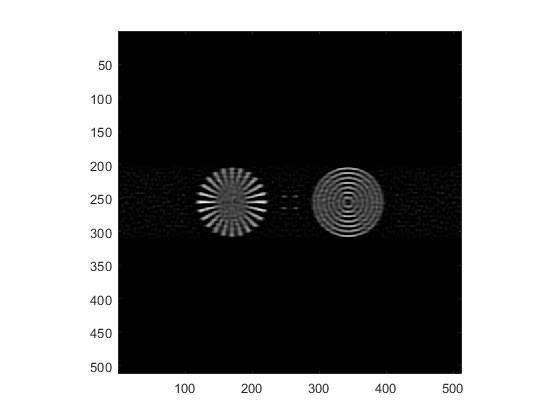

figure; imagesc(recMPIMGN3v3(:,:,locm3v3))
axis square
colormap gray

save('NoisyGAddedNoiseToRrecons.mat','recMPIMGN3v3','recMPIMGN2v3')

load('imgNF3Recon.mat')
load('imgN3Recon.mat')
load('imgN2Recon.mat')
load('recGN3.mat')
load('NoisyGAddedNoiseToRrecons.mat')

## Quantifying Performance

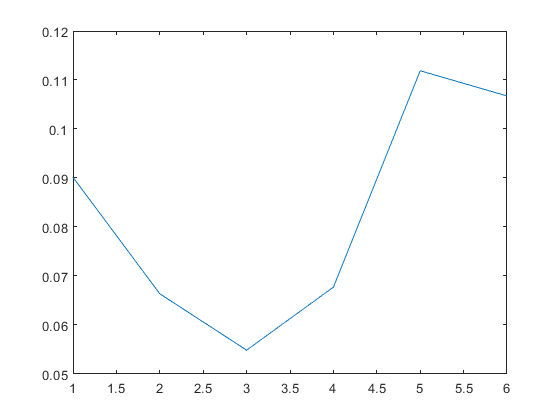

% Error in Each Harmonic image (Adding Noise to Randy's)
for ii=1:size(imgN3GNv2,3)
    errorharmsRGN3(ii)=immse(Norm(imgN3GNv2(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
for ii=1:size(imgN2GNv2,3)
    errorharmsRGN2(ii)=immse(Norm(imgN2GNv2(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
figure; plot(errorharmsRGN3)

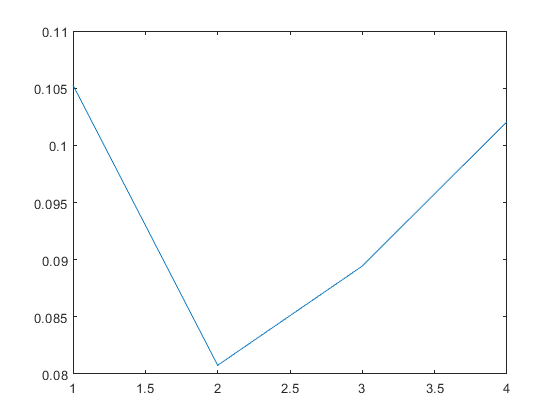

figure; plot(errorharmsRGN2)

% Corresponding error in reconstructions
eval2

eval2 = 0.0068

eval3

eval3 = 0.0055

%lines 637-693

Need to trim out these Harmonics

size(ImDataNoiseGN2v2)

ans =         1023        2559


TrimPadGN2=ImDataNoiseGN2v2(255:255+511,255:2048+254);
TrimPadGN2=reshape(TrimPadGN2,[512 512 4]);
for ii=1:4
    TrimPadGN2(:,:,ii)=circshift(circshift(Norm(TrimPadGN2(:,:,ii)),-2),-2,2);
end
size(ImDataNoiseGN3v2)

ans =         1023        3583


TrimPadGN3=ImDataNoiseGN3v2(255:255+511,255:3072+254);
TrimPadGN3=reshape(TrimPadGN3,[512 512 6]);
for ii=1:6
    TrimPadGN3(:,:,ii)=circshift(circshift(Norm(TrimPadGN3(:,:,ii)),-2),-2,2);
end

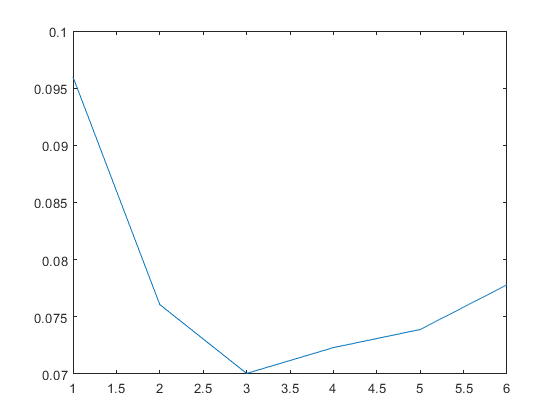

% Error in Each Harmonic image (Uncorrelated Noise version)
for ii=1:size(TrimPadGN3,3)
    errorharmsGN3(ii)=immse(Norm(TrimPadGN3(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
for ii=1:size(TrimPadGN2,3)
    errorharmsGN2(ii)=immse(Norm(TrimPadGN2(200:311,112:400,ii)),Norm(trueimage(200:311,112:400)));
    
end
figure; plot(errorharmsGN3)

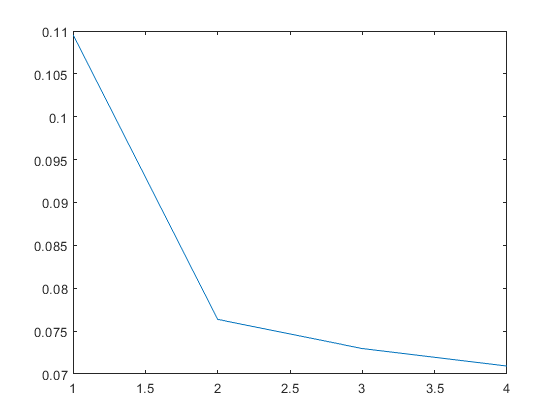

figure; plot(errorharmsGN2)

% Corresponding error in reconstructions
eval2v2

eval2v2 = 0.0037

eval3v2

eval3v2 = 0.0030

%lines 419-469

Try ssim??

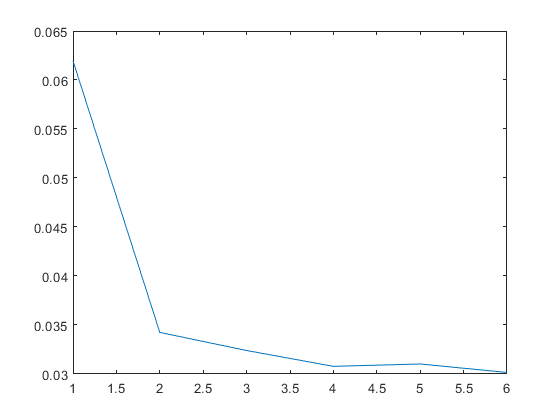

% Error in Each Harmonic image (Uncorrelated Noise version)
for ii=1:size(TrimPadGN3,3)
    errorharmsGN3s(ii)=ssim(Norm(TrimPadGN3(:,:,ii)),Norm(trueimage));
    
end
for ii=1:size(TrimPadGN2,3)
    errorharmsGN2s(ii)=ssim(Norm(TrimPadGN2(:,:,ii)),Norm(trueimage));
    
end
figure; plot(errorharmsGN3s)

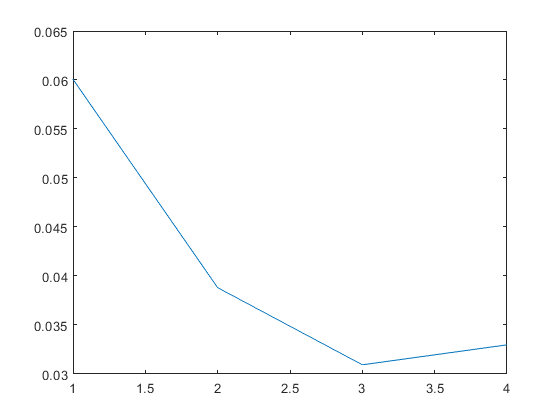

figure; plot(errorharmsGN2s)

% Corresponding error in reconstructions
eval2v2

eval2v2 = 0.0037

eval3v2

eval3v2 = 0.0030

%lines 419-469

Try pSNR??

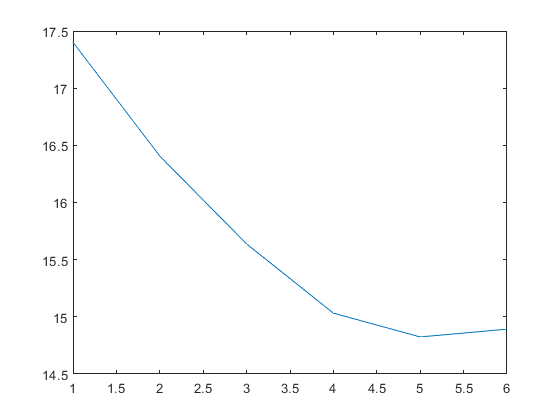

% Error in Each Harmonic image (Uncorrelated Noise version)
for ii=1:size(TrimPadGN3,3)
    errorharmsGN3p(ii)=psnr(Norm(TrimPadGN3(:,:,ii)),Norm(trueimage));
    
end
for ii=1:size(TrimPadGN2,3)
    errorharmsGN2p(ii)=psnr(Norm(TrimPadGN2(:,:,ii)),Norm(trueimage));
    
end
figure; plot(errorharmsGN3p)

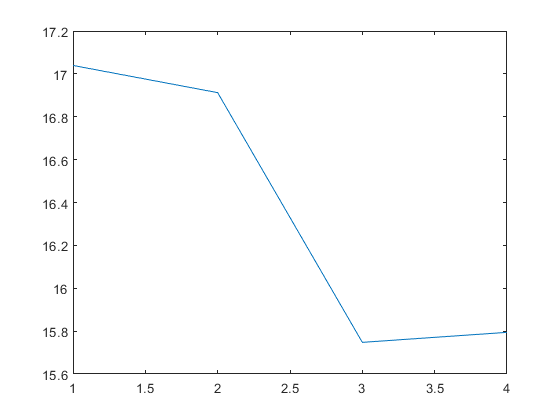

figure; plot(errorharmsGN2p)

% Corresponding error in reconstructions
eval2v2

eval2v2 = 0.0037

eval3v2

eval3v2 = 0.0030

%lines 419-469

Bar Graphs

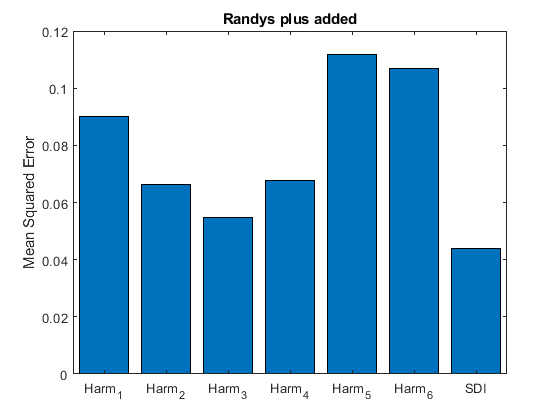

X = categorical({'Harm_1','Harm_2','Harm_3','Harm_4','Harm_5','Harm_6','SDI'});

Y = [errorharmsRGN3(1) errorharmsRGN3(2) errorharmsRGN3(3) errorharmsRGN3(4) errorharmsRGN3(5) errorharmsRGN3(6) immse(Norm(recMPIMGN3v3(200:311,112:400,locm3v3)),Norm(trueimage(200:311,112:400)))];
figure;
bar(X,Y)
ylabel('Mean Squared Error')
title('Randys plus added')

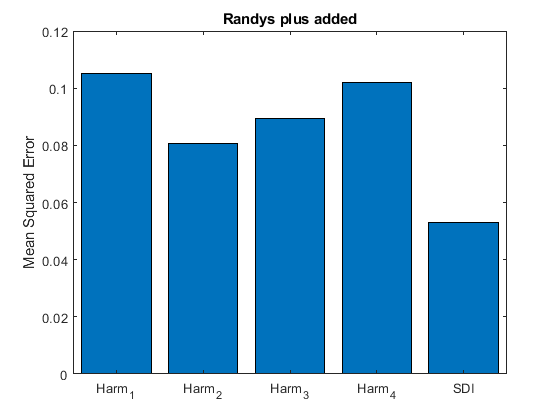

X2 = categorical({'Harm_1','Harm_2','Harm_3','Harm_4','SDI'});

Y2 = [errorharmsRGN2(1) errorharmsRGN2(2) errorharmsRGN2(3) errorharmsRGN2(4) immse(Norm(recMPIMGN2v3(200:311,112:400,locm2v3)),Norm(trueimage(200:311,112:400)))];
figure;
bar(X2,Y2)
ylabel('Mean Squared Error')
title('Randys plus added')

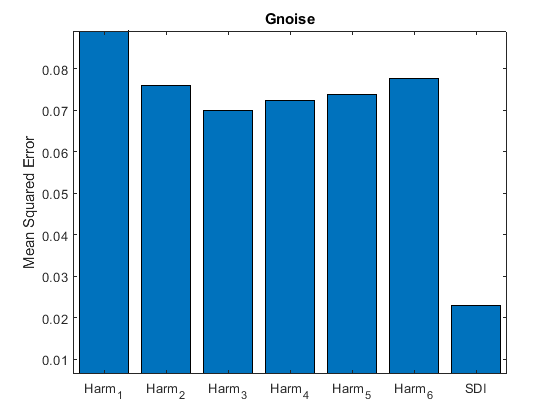

X3 = categorical({'Harm_1','Harm_2','Harm_3','Harm_4','Harm_5','Harm_6','SDI'});

Y3 = [errorharmsGN3(1) errorharmsGN3(2) errorharmsGN3(3) errorharmsGN3(4) errorharmsGN3(5) errorharmsGN3(6) immse(Norm(recMPIMGN3v2(200:311,112:400,locm3v2)),Norm(trueimage(200:311,112:400)))];
figure;
bar(X3,Y3)
ylabel('Mean Squared Error')
title('Gnoise')

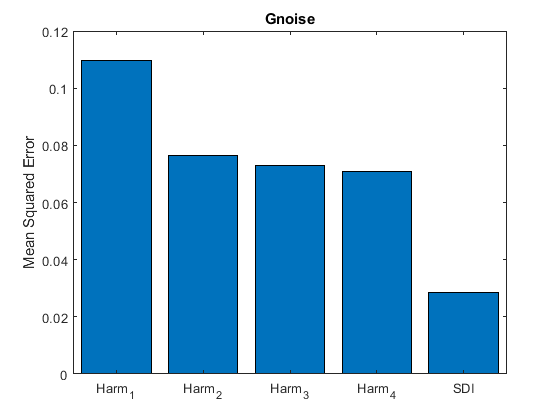


X4 = categorical({'Harm_1','Harm_2','Harm_3','Harm_4','SDI'});

Y4 = [errorharmsGN2(1) errorharmsGN2(2) errorharmsGN2(3) errorharmsGN2(4) immse(Norm(recMPIMGN2v2(200:311,112:400,locm2v2)),Norm(trueimage(200:311,112:400)))];
figure;
bar(X4,Y4)
ylabel('Mean Squared Error')
title('Gnoise')

## Same Thing For Noise Free

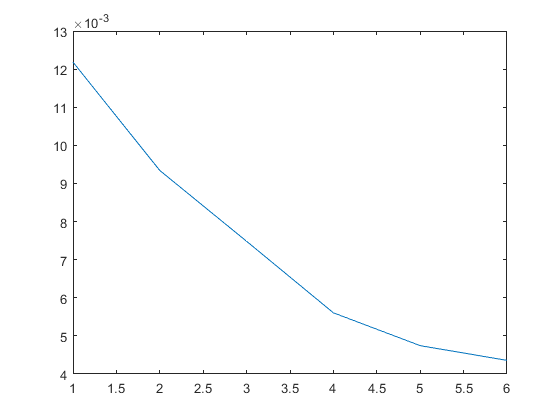

% Error in Each Harmonic image (Uncorrelated Noise version)
for ii=1:size(imgNF3,3)
    errorharmsNF3(ii)=immse(Norm(imgNF3(:,:,ii)),Norm(trueimage));
    
end
for ii=1:size(TrimPadGN2,3)
    errorharmsNF2(ii)=immse(Norm(imgNF2(:,:,ii)),Norm(trueimage));
    
end
figure; plot(errorharmsNF3)

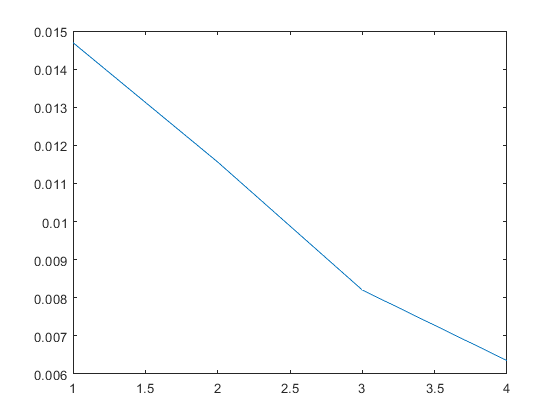

figure; plot(errorharmsNF2)

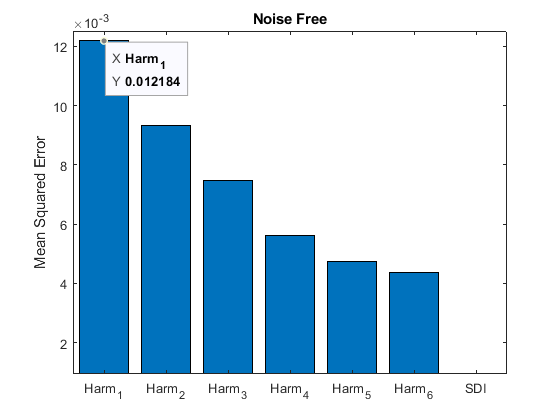

X5 = categorical({'Harm_1','Harm_2','Harm_3','Harm_4','Harm_5','Harm_6','SDI'});

Y5 = [errorharmsNF3(1) errorharmsNF3(2) errorharmsNF3(3) errorharmsNF3(4) errorharmsNF3(5) errorharmsNF3(6) immse(Norm(NF3),Norm(trueimage))];
figure;
bar(X5,Y5)
ylabel('Mean Squared Error')
title('Noise Free')

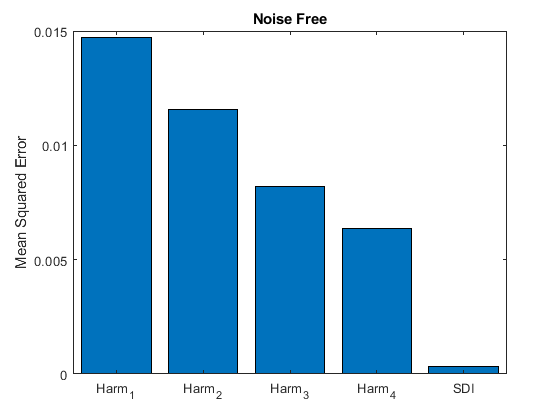

X6 = categorical({'Harm_1','Harm_2','Harm_3','Harm_4','SDI'});

Y6 = [errorharmsNF2(1) errorharmsNF2(2) errorharmsNF2(3) errorharmsNF2(4) immse(Norm(NF2),Norm(trueimage))];
figure;
bar(X6,Y6)
ylabel('Mean Squared Error')
title('Noise Free')

## Save Reconstructed Images

RGN3=recMPIMGN3v3(:,:,locm3v3);
RGN2=recMPIMGN2v3(:,:,locm2v3);
GN3=recMPIMGN3v2(:,:,locm3v2);
GN2=recMPIMGN2v2(:,:,locm2v2);
save('ReconstructedNoisyImages.mat','RGN3','RGN2','GN3','GN2');

NF3=recMPIMNF3(:,:,end);
NF2=recMPIMNF2(:,:,end);
save('ReconstructedNoNoiseImages.mat','NF3','NF2');

## Spatial Frequencies

Ntheta=20;
trueimFave=GabeRadialAvg(abs(fftshift(fft2(trueimage))),Ntheta);
FaveRGN3=GabeRadialAvg(abs(fftshift(fft2(RGN3))),Ntheta);
FaveRGN2=GabeRadialAvg(abs(fftshift(fft2(RGN2))),Ntheta);
FaveGN3=GabeRadialAvg(abs(fftshift(fft2(GN3))),Ntheta);
FaveGN2=GabeRadialAvg(abs(fftshift(fft2(GN2))),Ntheta);
FaveNF3=GabeRadialAvg(abs(fftshift(fft2(NF3))),Ntheta);
FaveNF2=GabeRadialAvg(abs(fftshift(fft2(NF2))),Ntheta);

FaveGNH1=GabeRadialAvg(abs(fftshift(fft2(TrimPadGN3(:,:,1)))),Ntheta);
FaveGNH2=GabeRadialAvg(abs(fftshift(fft2(TrimPadGN3(:,:,2)))),Ntheta);
FaveGNH3=GabeRadialAvg(abs(fftshift(fft2(TrimPadGN3(:,:,3)))),Ntheta);
FaveGNH4=GabeRadialAvg(abs(fftshift(fft2(TrimPadGN3(:,:,4)))),Ntheta);
FaveGNH5=GabeRadialAvg(abs(fftshift(fft2(TrimPadGN3(:,:,5)))),Ntheta);
FaveGNH6=GabeRadialAvg(abs(fftshift(fft2(TrimPadGN3(:,:,6)))),Ntheta);

FaveRGNH1=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,1)))),Ntheta);
FaveRGNH2=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,2)))),Ntheta);
FaveRGNH3=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,3)))),Ntheta);
FaveRGNH4=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,4)))),Ntheta);
FaveRGNH5=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,5)))),Ntheta);
FaveRGNH6=GabeRadialAvg(abs(fftshift(fft2(imgN3GNv2(:,:,6)))),Ntheta);

FaveNF3H1=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,1)))),Ntheta);
FaveNF3H2=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,2)))),Ntheta);
FaveNF3H3=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,3)))),Ntheta);
FaveNF3H4=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,4)))),Ntheta);
FaveNF3H5=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,5)))),Ntheta);
FaveNF3H6=GabeRadialAvg(abs(fftshift(fft2(imgNF3(:,:,6)))),Ntheta);

FaveN3H1=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,1)))),Ntheta);
FaveN3H2=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,2)))),Ntheta);
FaveN3H3=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,3)))),Ntheta);
FaveN3H4=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,4)))),Ntheta);
FaveN3H5=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,5)))),Ntheta);
FaveN3H6=GabeRadialAvg(abs(fftshift(fft2(imgN3(:,:,6)))),Ntheta);

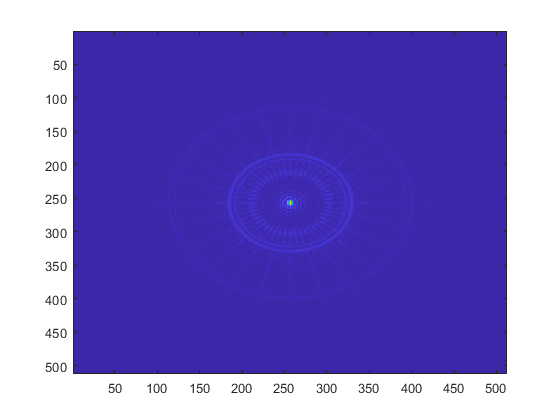


figure; imagesc((abs(fftshift(fft2(trueimage)))))

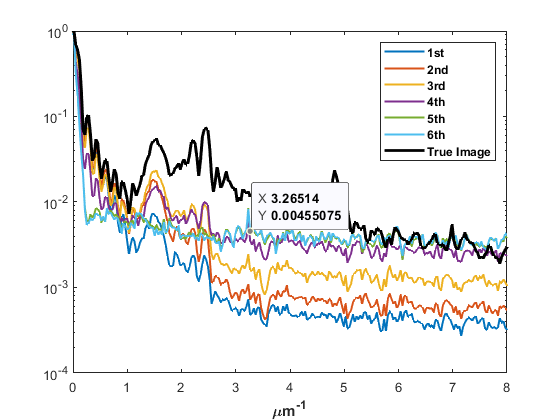

figure; semilogy(fx,(Norm(FaveN3H1)),'LineWidth',1.5)%semilogy(fx,(Norm(FaveGN3)),'LineWidth',2)
hold on


semilogy(fx,(Norm(FaveN3H2)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveN3H3)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveN3H4)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveN3H5)),'LineWidth',1.5)
semilogy(fx,(Norm(FaveN3H6)),'LineWidth',1.5)
semilogy(fx,(Norm(trueimFave)),'k','LineWidth',2)
xlim([0 8])
xlabel('\mum^{-1}','FontWeight','Bold')
legend({'1st','2nd','3rd','4th','5th','6th','True Image'},'FontWeight','Bold')

% semilogy((Norm(FaveN3H5(end/2:end))))
% semilogy((Norm(FaveN3H6(end/2:end))))